# **IO325 & IO336 - Analog Loop Back with Oversampling**

This example demonstrates the use of the analog input interface in oversampling mode. The analog signals are sampled based on the I/O module internal clock at the maximum sampling rate of 1.5 MSPS. The average value is computed over a defined interval (number of samples) on the I/O module. When the CPU wakes up, it reads out the most recent average value. The number of samples which are considered for the average value can be defined in the driver block. The example describes the required driver blocks and settings. This setup helps to mitigate noise on a sampled analog signal.

The model generates a sine wave signal with noise on the analog output. The analog output is configured for frame-based mode as described in more detail in the example [IO325 & IO336 - Frame-Based Analog Loopback](https://www.speedgoat.com/help/slrt/page/examples/IO325_IO336_AnalogLoopbackDMA). The analog output pin of the module must be wired to the analog input to read back the sine wave. The oversampling mode helps to mitigate the noise on the signal.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO325 or IO336 I/O module installed

- A Speedgoat configuration file for the IO325 or IO336 module (every configuration file for these modules supports the analog interfaces)

- Connector cable from the I/O module to the terminal board

- 1x 100-pin terminal board with jumper wires

- Optional: Oscilloscope to measure the analog signals

### Test Setup

Connect the IO325 or IO336 module with the cable to the 100-pin terminal board. Note the indications on the connectors of the cable to make sure the right connector is connected to the I/O module and terminal board respectively (the cable is not symmetrical). The arrows on the connectors help to make sure that the orientation is right. Locate DAC channel 1 and connect it to the positive pin of the differential analog input channel 1 according to the table below. The analog output signal is single ended. Therefore, connect the negative pin of the differential analog input channel to ground.

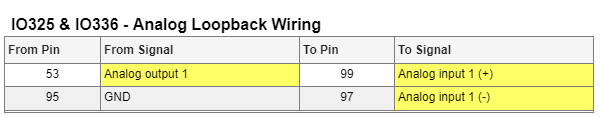

The [IO325 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io325_160k_pin_mapping) and [IO336 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_325k_pin_mapping) are identical regarding the lower order analog channels. The channel count is different between the two modules. The IO336 has twice as many analog input and output channels. The wiring table above is valid for both modules.

## Initialize and Open the Simulink Model

Open the Simulink model manually or use the following commands.


 

% Open Simulink model
modelName = 'sgMdl_IO325_IO336_AnalogLoopbackOversampling';
open_system(modelName);


Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select a configuration file. This example only requires analog interfaces, which are supported by any configuration file for the IO325 or IO336 by default.

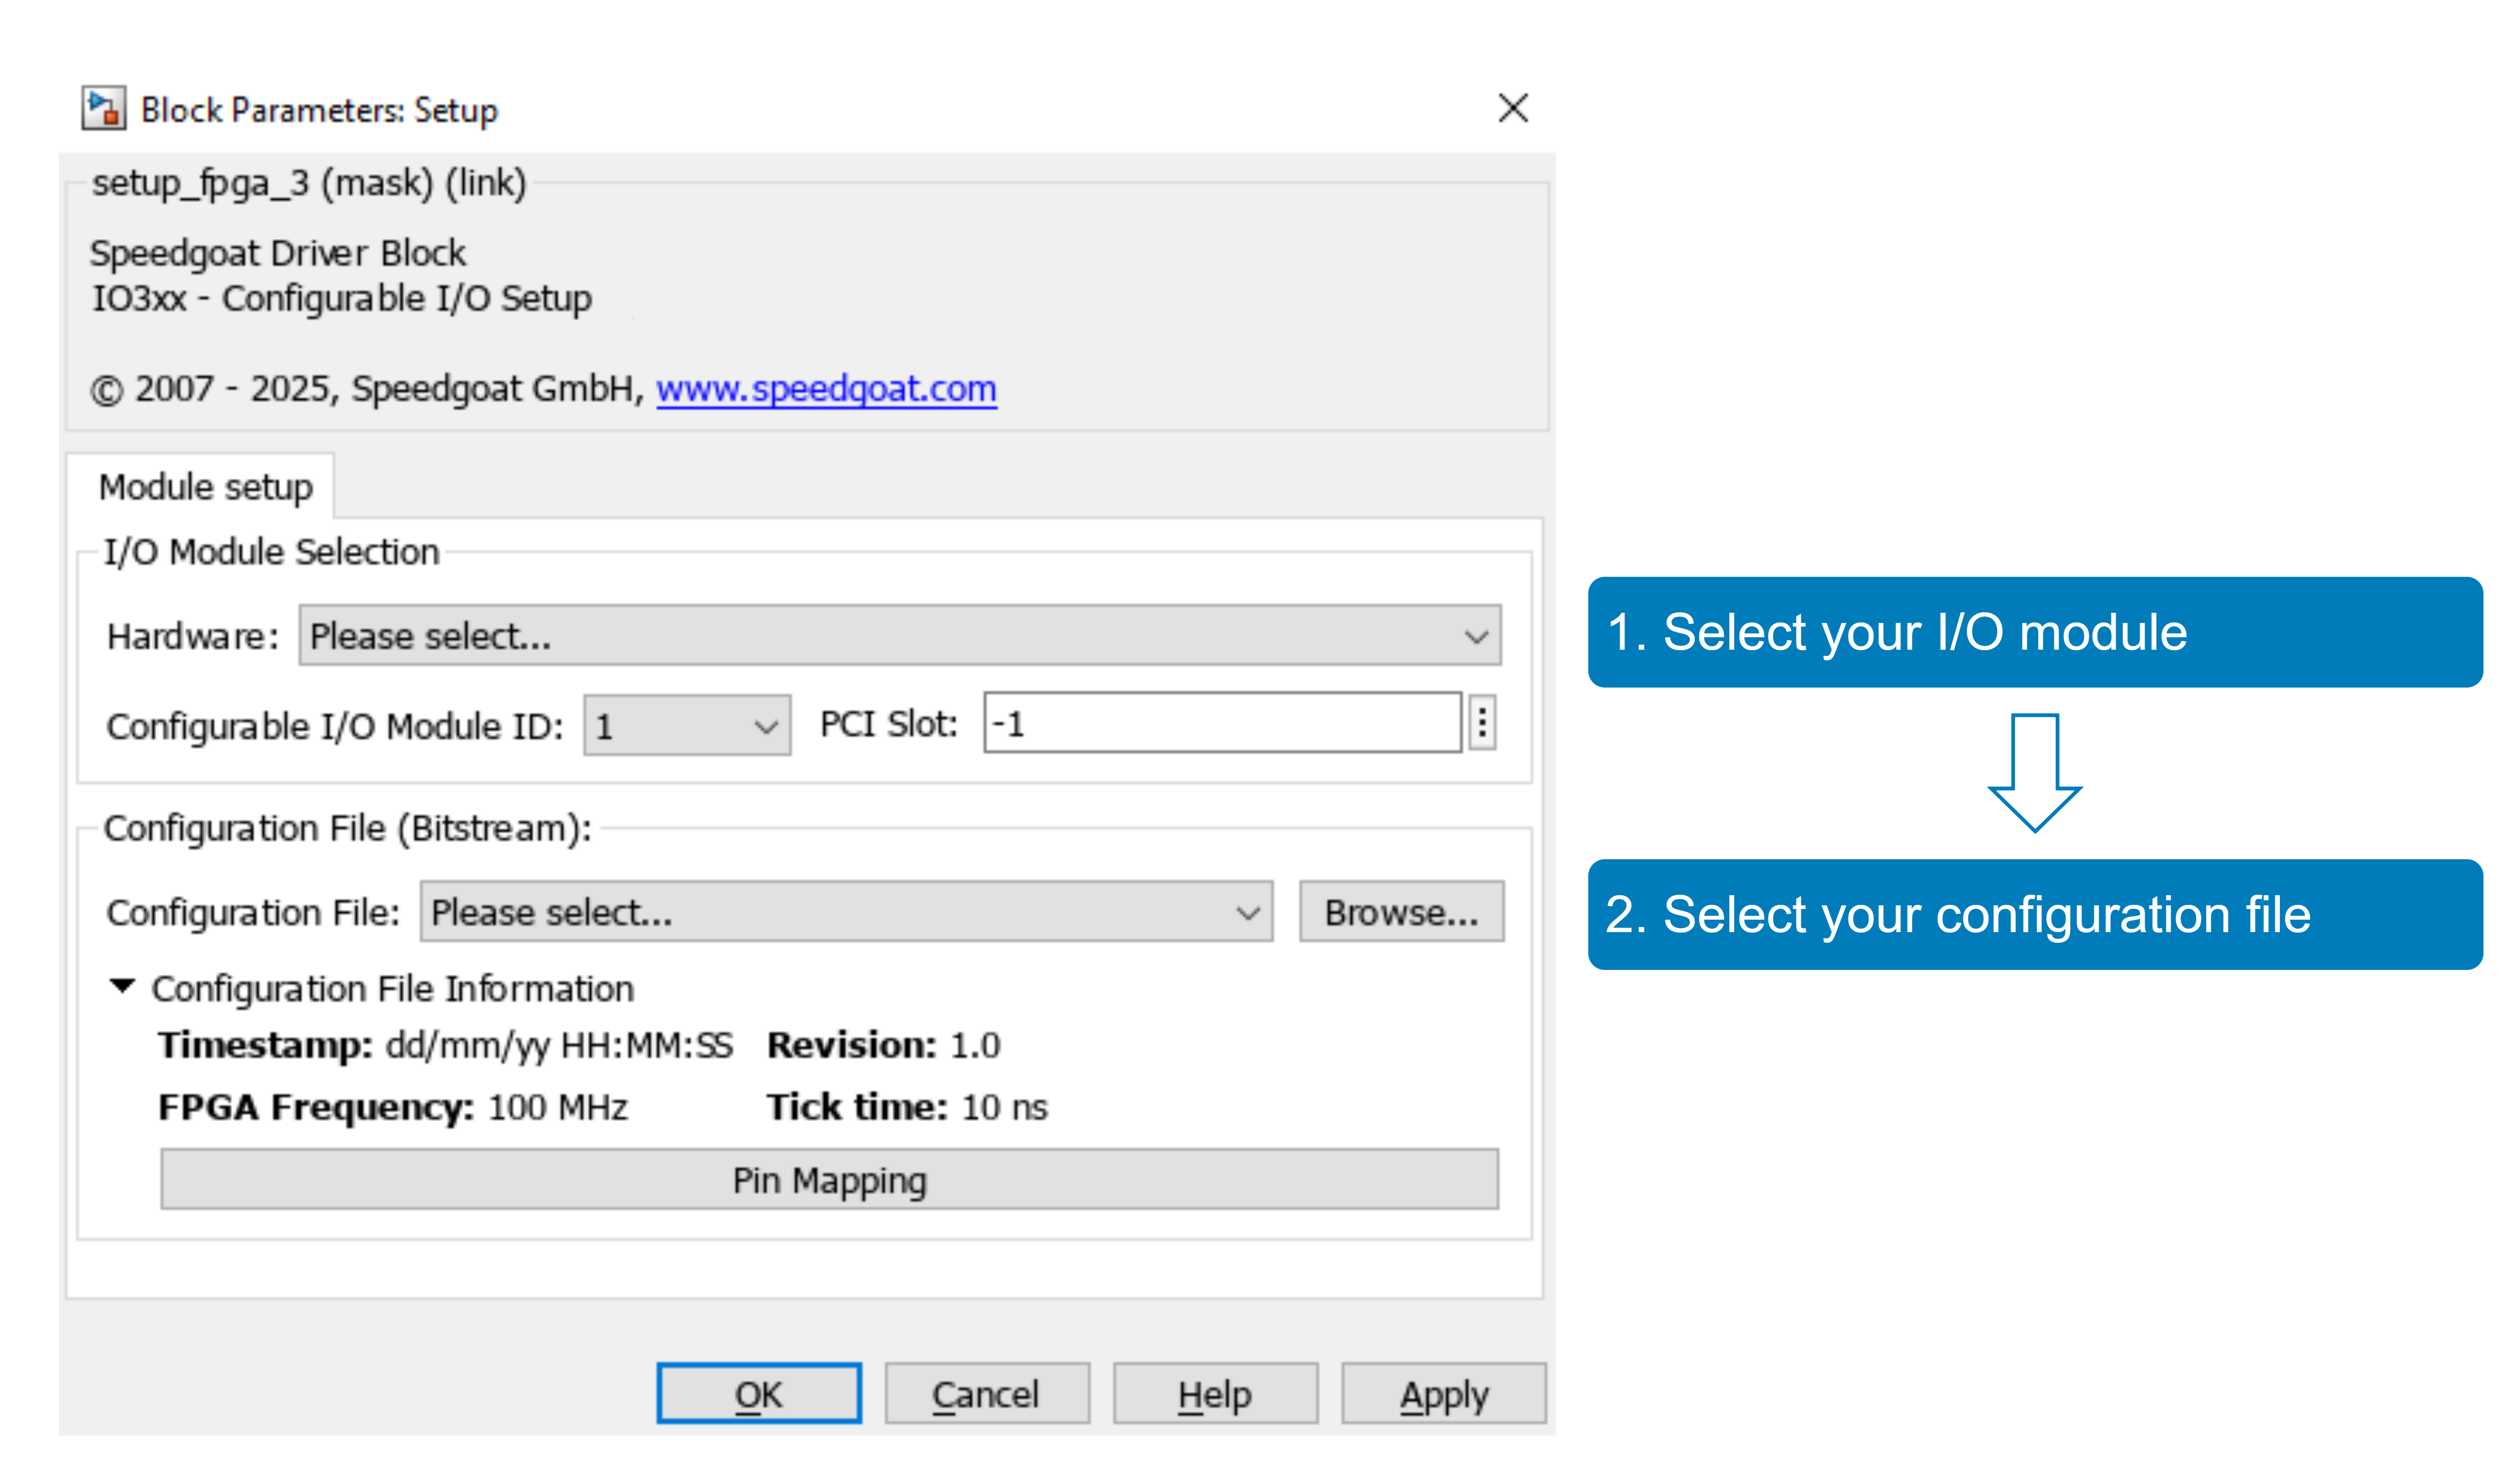

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### General Setup

The Simulink model features the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io336_325k), [IO336 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_setup_v1), [IO336 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_input_v1), [IO336 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_output_v1) and [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) blocks. The analog driver blocks used in this model support the IO325 and IO336 modules. Both modules use the same analog driver blocks which appear twice in the library browser, in the IO325 and IO336 section of the Speedgoat IO3xx Analog I/O driver block library.

Settings are shared between the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io336_325k), [IO336 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_setup_v1), [IO336 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_input_v1), and [IO336 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_output_v1) blocks. Ensure that you select the same FPGA Module Identifier in the mask of these blocks. This is important for Simulink to identify which blocks belong together and which I/O module they address. This is especially important if you have multiple configurable I/O modules in your system.

The analog outputs of the IO325 and IO336 are single ended. Note that the analog input circuits expect differential signals. The example model uses one analog output channel to generate one sine wave signal with noise. One analog input channel is used to read back the signal for logging and visualization.

### Analog Output in Frame-Based Operation Mode

The analog output is operated in frame-based mode to achieve a high update rate of the analog output. This is important for this example to generate the noise on the signal. The model step time is set to 100 µs. The frame size is set to 100. Therefore, the analog outputs are updated based on the I/O module internal clock at a rate of 1 MSPS. An interrupt is emitted every 100 µs to wake up the CPU. The entire CPU model is computed when an interrupt is received. This behavior is configured in the [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block (**Use as model trigger **checkbox). The frame-based mode is described in more detail in the [IO325 & IO336 - Frame-Based Analog Loopback](https://www.speedgoat.com/help/slrt/page/examples/IO325_IO336_AnalogLoopbackDMA) example.

### Analog Input with Oversampling

The analog input is configured to run in oversampling mode. In this configuration, the ADC acquires samples as fast as possible in free running mode. As soon as the conversion process has ended, the next conversion is initiated. This results in a sampling rate of 1.5 MSPS. The CPU does not read out every sampled value. Instead, an average value is computed on the module. The **Oversampling Factor **parameter in the [IO336 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_setup_v1) driver block defines how many samples are used to compute the average value. The [IO336 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_input_v1) block reads the latest available average value from the I/O module when the CPU model is executed.

The following graph shows the behavior and timing of the oversampling mode for an **Oversampling Factor** of four. When four samples are acquired, the module computes the average value. The latest average value is read by the CPU and processed in the model.

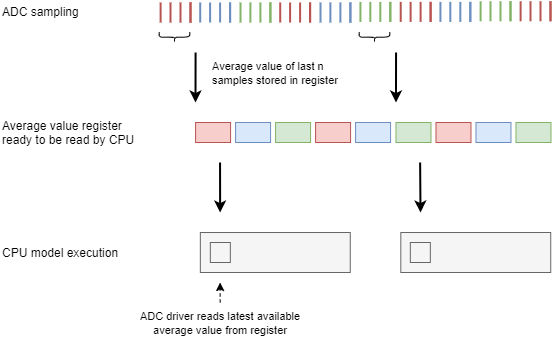

In this example, the CPU runs based on the interrupt from the analog output interface. The analog input interface in oversampling mode does not require synchronization between the I/O module and CPU.

### Sample Rate and Frame Settings

The model is configured to run at a fixed step sample rate of 100 µs. The frame size for the analog outputs is 100 which results in an update rate of 1 MSPS. The frequency of the sine wave at the analog output is 100 Hz. 


 

Ts = 1e-4;                          % CPU model sample step size [s]
SineFrequency = 100;                % Frequency of generated sine wave signals [Hz]
AnalogOutputFrameSize = 100;        % Frame size for analog output [samples per frame]
AnalogInputSampleRate = 1e6;        % Sample rate of the analog inputs [samples per second]


### ADC and DAC Settings

To see the setup and parametrization of the ADC and DAC channels, open the [IO336 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_setup_v1) block.

#### Tab: Main (Analog Input Trigger section)

In the **Main** tab, the **Analog Input Trigger** section shows the ADC trigger settings of this model.

The **ADC Sample Trigger** parameter is set to **I/O Module Clock. **The **Enable DMA Interrupt** checkbox is disabled. The **Oversampling Factor** can be defined in the drop-down list for each group of channels independently. The **Oversampling Factor **can be between 1 (none) and 64 and must be a power of 2. For this example, we use an **Oversampling Factor** of 64 for the first channel group for maximum noise mitigation.

#### Tab: Main (Analog Output Trigger section)

The **DAC Sample Trigger** is also set to **I/O Module Clock.** However, the **Enable DMA Interrupt** checkbox is enabled for the analog output interface. The **Frame-Based Settings** box is visible.

The **Output Block Sample Time** is defined based on the workspace variable Ts (100 µs). This is the rate at which we want the [IO336 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_output_v1) driver block to be executed on the CPU. The **Frame Size** is set to 100 based on the workspace variable AnalogOutputFrameSize. The **DAC Sample Rate** is set to -1. Only two out of these three parameters can be explicitly defined. The third one, in this case the DAC Sample Rate, is computed by the driver and must be set to -1. The parameter is evaluated based on the other two parameters, in this case the **Output Block Sample Time** and the **Frame Size**.

The **FIFO Threshold** defines when the analog output interface on the I/O module triggers an interrupt. The interrupt is emitted to signal to the CPU that the next frame must be written to the FIFO buffer of the analog output interface. The module reads out one sample at a time from the FIFO buffer to update the DAC. In this example we set the FIFO Threshold to 20 % of the frame size. When the number of samples in the buffer falls below 20 samples, the interrupt is emitted. The CPU wakes up and the  [IO336 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_output_v1) driver block writes the next frame of 100 samples to the FIFO buffer. The **FIFO Threshold** must be sufficiently high to give the driver block enough time to write new samples, before the FIFO buffer is empty.

#### Tab: Analog Inputs

In the **Analog Inputs** tab of the [IO336 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_setup_v1) block, you can see which ADC channels are active, and the configured voltage range. In this example, only ADC channel 1 is used.

#### Tab: Analog Outputs

In the **Analog Outputs** tab of the [IO336 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_setup_v1) block, you can see which DAC channels are active, and the configured voltage range. Only channel 1 is active for this example.

## Timing and Interrupt

The [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block is used to configure the interrupt. You must select the right interrupt, based on your I/O module. Open the block mask and click the **Select Interrupt** button. The interrupt selector window pops up. Depending on your I/O module, select the **Speedgoat IO325-160k Analog output interrupt** or **Speedgoat IO336-325k Analog output interrupt.**

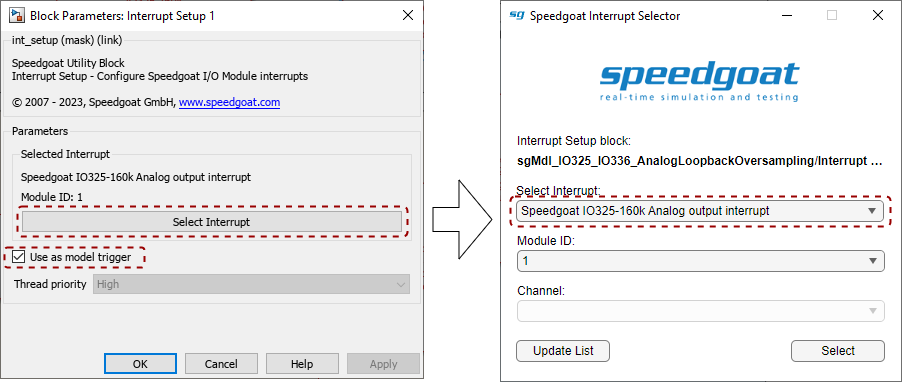

The **Use as model trigger** checkbox is active in the mask of the [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block. This means that the entire CPU model is executed every time the analog output interrupt is received.

The model runs at a relatively low sample rate of 100 µs. The computational load of the first sample step may be higher than for the following steps. The [Overload Options](https://www.mathworks.com/help/slrealtime/io_ref/slrtoverloadoptions.html) block is used to avoid a CPU overload at model start.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model. The model is configured to run for a duration of 1 second.

 

% Set the stop time to 1 seconds
set_param(modelName,'StopTime','1');

% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Start the real-time application
tg.start;
pause(stoptime+1);

## Show and Analyze the Signals

The File Log block is used in the model to log the sine wave generated at the analog output and the looped back signal received by the analog input. The signals are written to the hard drive of the real-time target machine and transferred to the host computer as soon as the model stops. The signals can then be displayed in the Simulation Data Inspector (SDI). Click the **Data Inspector** button in the **REAL-TIME** tab in the Simulink window to open SDI or run the following code section.

 
% Get and configure SDI Run
SDIRun      = Simulink.sdi.Run.getLatest;   % get the latest SDI run
SDIRun.name = 'Real-Time Simulation';

% clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(1,1);                     % layout with one plots

% get signals by name (signal label in Simulink)
AnalogOutputSignal = SDIRun.getSignalsByName('DAC 1');
AnalogInputSignal = SDIRun.getSignalsByName('ADC 1');

% set line color
AnalogInputSignal.LineColor = [0.6353, 0.0784,0.1843];
AnalogOutputSignal.LineColor = [0.3010, 0.7450, 0.9330];

% assign signals to subplots
plotOnSubPlot(AnalogOutputSignal,1,1,true);
plotOnSubPlot(AnalogInputSignal,1,1,true);

% open SDI
Simulink.sdi.view;
Simulink.sdi.setSubplotLimits(1,1,"tMin",0.95,"tMax",1);   % set time span
Simulink.sdi.setSubplotLimits(1,1,"yMin",-1.5,"yMax",1.5);         % set y-zoom

The plot shows the noisy sine wave signal connected to the analog output and the signal acquired by the analog input. The noise is clearly reduced using the oversampling factor of 64.

### 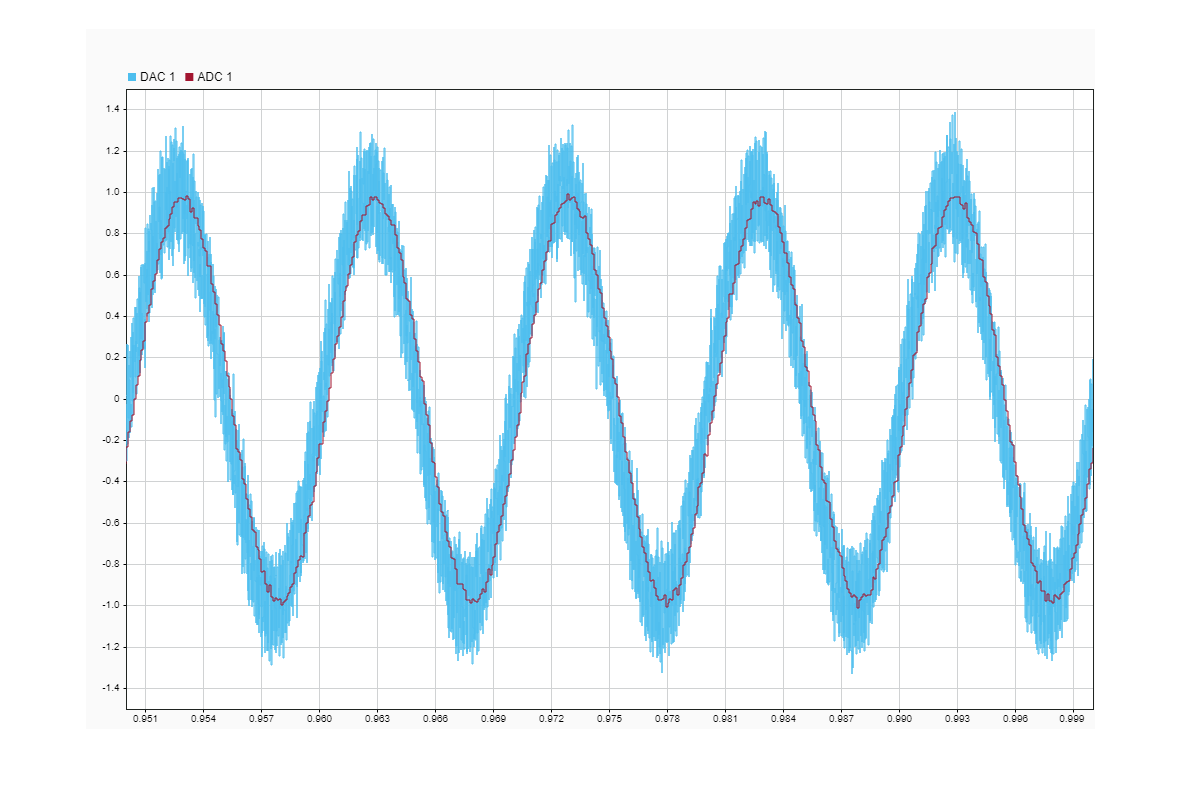

## Additional References

- [IO325 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io325_160k)

- [IO336 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io336_325k)

- [Analog IO325](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_analog_io325_160k)

- [Analog IO336](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_analog_io336_325k)